% GET MAPS FILES FOR THE SESSION
% GET TOPOX,Y, SHOW POLAR MAPS
% get topox & topoy MAPS & make polar maps

% topox
[f p] = uigetfile('*.mat','topox maps file')

f = 070421_G6H305RT_RIG2_TOPOXmaps.mat

p = F:\Kristen\Widefield2\070421_G6H305RT_RIG2\070421_G6H305RT_RIG2_TOPOX\

load(fullfile(p,f),'mapNorm');
topox = polarMap(mapNorm{3}); % polar map = projecting features from plane to sphere


% show polar map
f1 = figure

f1 =   Figure (27) with properties:

      Number: 27
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [465.6667 460.3333 573.3333 436.6667]
       Units: 'pixels'

  Show all properties


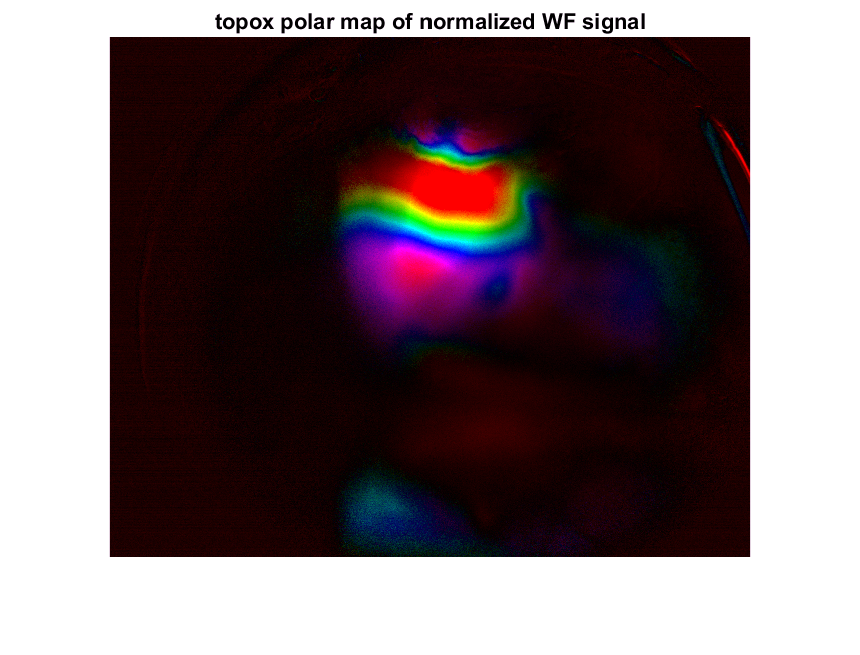

imshow(topox)
title('topox polar map of normalized WF signal')


% topoy
[f p] = uigetfile('*.mat','topoy maps file')

f = 070421_G6H305RT_RIG2_TOPOYmaps.mat

p = F:\Kristen\Widefield2\070421_G6H305RT_RIG2\070421_G6H305RT_RIG2_TOPOY\

load(fullfile(p,f),'mapNorm','map');
topoy = polarMap(mapNorm{3});


% polar map
f2 = figure

f2 =   Figure (28) with properties:

      Number: 28
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [465.6667 460.3333 573.3333 436.6667]
       Units: 'pixels'

  Show all properties


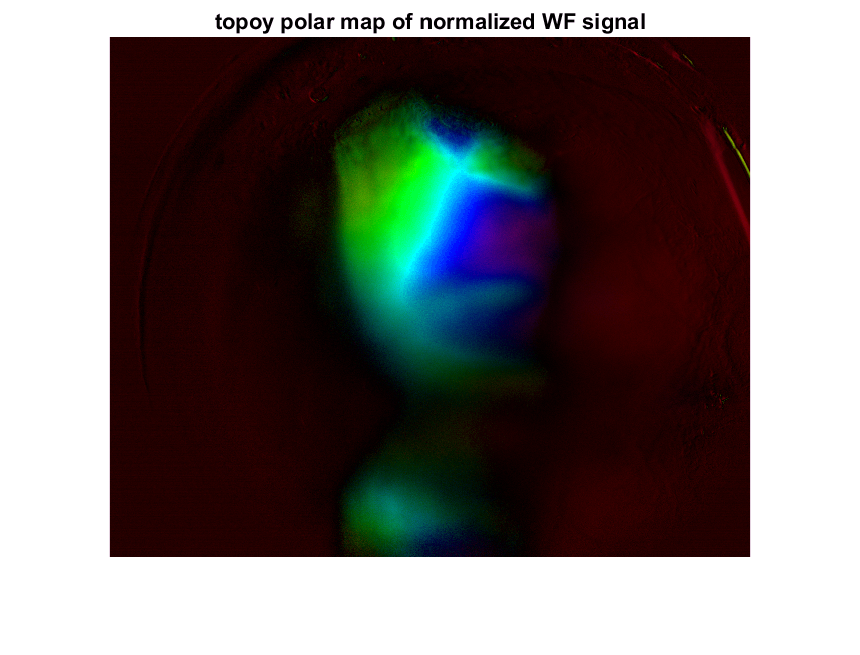

imshow(topoy)
title('topoy polar map of normalized WF signal')


%% get THRESH MAPS

[f p] = uigetfile('*.mat','maps file');

downsize = 0.25; % why resize by this factor?
load(fullfile(p,f));

%%  DOWNSIZE all 3 videos

df = dfof_bg;
% df = imresize(dfof_bg,downsize); % if green light, gets downsized in dfofMovie I think..)
topox = imresize(topox,downsize);
topoy = imresize(topoy,downsize);


% LOADING MOUSE EXPERIMENT VARIABLES - saved out in dfofMovie

% add PATH, but nagivate to correct OUTPUT FOLDER for saving vars

% addpath F:\Kristen\Widefield2\041021_G6H277RT_RIG2\balldata_G6H277RT 
% addpath F:\Kristen\Widefield2\041121_G6H277RT_RIG2\balldata_G6H277RT
% addpath F:\Kristen\Widefield2\052021_G6H277RT_RIG2\balldata_G6H277RT
% addpath F:\Kristen\Widefield2\052121_G6H277RT_RIG2\balldata_G6H277RT
% addpath F:\Kristen\Widefield2\060121_EE81LT_RIG2\balldata_EE81LT
% addpath F:\Kristen\Widefield2\060221_EE81LT_RIG2\balldata_EE81LT
% addpath F:\Kristen\Widefield2\060221_EE81LT_RIG2\balldata_EE81LT
% addpath F:\Kristen\Widefield2\060221_G6H277RT_RIG2\balldata_G6H277RT
% addpath F:\Kristen\Widefield2\060321_EE81LT_RIG2\balldata_EE81LT
% addpath F:\Kristen\Widefield2\060721_EE81LT_RIG2\balldata_G6H277RT 
% addpath F:\Kristen\Widefield2\061521_G6H277RT_RIG2\balldata_G6H277RT
% addpath F:\Kristen\Widefield2\060821_G6H277RT_RIG2\balldata_G6H277RT
% addpath F:\Kristen\Widefield2\060221_G6H277RT_RIG2\balldata_G6H277RT
addpath F:\Kristen\Widefield2\070421_G6H305RT_RIG2\balldata_G6H305RT
% addpath F:\Kristen\Widefield2\070921_G6H305RT_RIG2\balldata_G6H305RT
% addpath F:\Kristen\Widefield2\070521_EE124RN_RIG2\balldata_EE124RN
% addpath F:\Kristen\Widefield2\070521_EE124LT_RIG2\balldata_EE124LT
% addpath F:\Kristen\Widefield2\070521_G6H305LT_RIG2\balldata_G6H305LT
% addpath F:\Kristen\Widefield2\070921_G6H305RT_RIG2\balldata_G6H305RT
% addpath F:\Kristen\Widefield2\070921_EE124RN_RIG2\balldata_EE124RN

% load SUBJ mat file: 

load('G6H305RT_subj.mat') % CHECK each time

% load SESSIONS mat file (doBehavior generates one of these files per session):

% load('20210411T123140_25.mat') % 277RT 041121
% load('20210410T195352_20.mat') % 277RT 041021
% load('20210520T153642_29.mat') % 277RT 052021
% load('20210521T132731_36.mat') % 277RT 052121 (reg thresh)
% load('20210521T144316_37.mat') % 277RT 052121 (threshless)
% load('20210601T134850_11.mat') % EE81LT 060121
% load('20210602T161152_12.mat') % EE81LT 060221
% load('20210602T134136_38.mat') % 277RT 060221
% load('20210603T103913_13.mat') % 277RT 060321
% load('20210607T161721_39.mat') % 277RT [MIS-named EE81LT] 060721
% load('20210615T141420_40.mat') % 277RT 061521
load('20210704T135539_1.mat') % 305RT 070421 
% load('20210709T134605_2.mat') % 305RT 070921 
% load('20210706T124226_1.mat') % EE124RN 070521
% load('20210706T153005_1.mat') % EE124LT 070521
% load('20210706T184243_2.mat') % G6H305LT 070521, 1262 trials
% load('20210709T134605_2.mat')
% load('20210709T161144_2.mat')


% FIG TITLES

% mouse id
subjName = subjData{1,1}.name; 

% date & name
%[filepath,name,ext] = fileparts('20210411T123140_25.mat'); % 277RT 041121
% [filepath,name,ext] = fileparts('20210410T195352_20.mat'); % 277RT 041021
% [filepath,name,ext] = fileparts('20210520T153642_29.mat') % 277RT 052021
% [filepath,name,ext] = fileparts('20210521T132731_36.mat'); % 277RT 0521021
% [filepath,name,ext] = fileparts('20210601T134850_11.mat'); % EE81LT 060121
% [filepath,name,ext] = fileparts('20210602T161152_12.mat'); % EE81LT 060221
% [filepath,name,ext] = fileparts('20210602T134136_38.mat') % 277RT 060221
% [filepath,name,ext] = fileparts('20210607T161721_39.mat'); % 277RT 060721
% [filepath,name,ext] = fileparts('20210615T141420_40.mat'); % 277RT 061521 
[filepath,name,ext] = fileparts('20210704T135539_1.mat') % 305RT 070421

filepath = 

name = 20210704T135539_1

ext = .mat

% [filepath,name,ext] = fileparts('20210706T124226_1.mat') % 124RN 070521
% [filepath,name,ext] = fileparts('20210706T153005_1.mat') % EE124LT 070521
% [filepath,name,ext] = fileparts('20210706T184243_2.mat') % G6H305LT 070521, 1262 trials
% [filepath,name,ext] = fileparts('20210709T134605_2.mat') % G6H305RT 070921 
% [filepath,name,ext] = fileparts('20210709T161144_2.mat') % EE124RN 070921

datePart = name(1:8);
year = datePart(1:4);
month = datePart(5:6);
day = datePart(7:8);
date = sprintf('%s ', month, day, year);

display(date)

date = 07 04 2021 

display(subjName)

subjName = G6H305RT

% CROP FOV


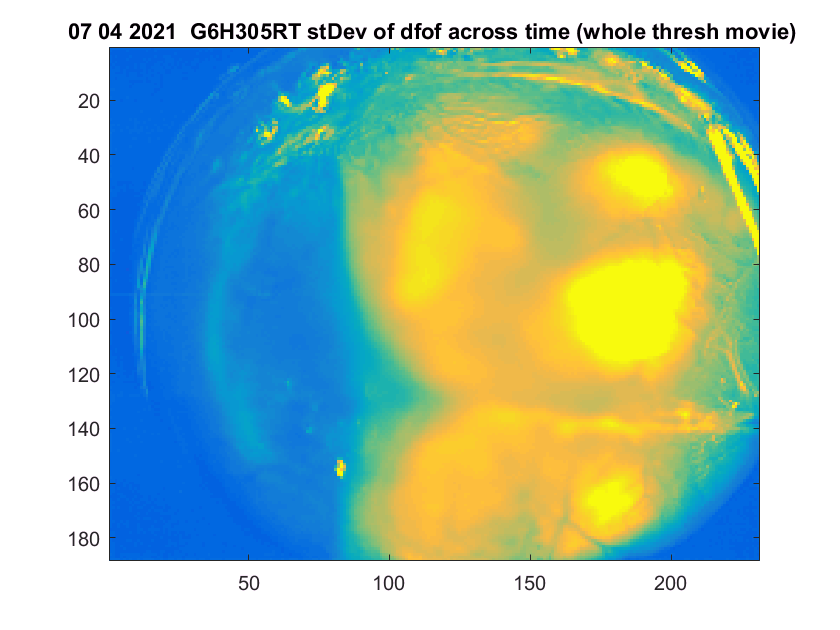

% 1st step: PICK image TO CROP from DF
% std of df gives us a general sense of how much variation there is across al trials
% we also use this to crop in next section
stdMap = std(df(:,:,1:10:end),[],3); % only take every 10 frames of df (don't need all, why?). taking std across 3rd dimension, time
figure;
range = [0 0.04];
% colormap jet
imagesc(stdMap,range)% 
clear titleText
titleText = 'stDev of dfof across time (whole thresh movie)';
title(sprintf('%s ',date,subjName,titleText))

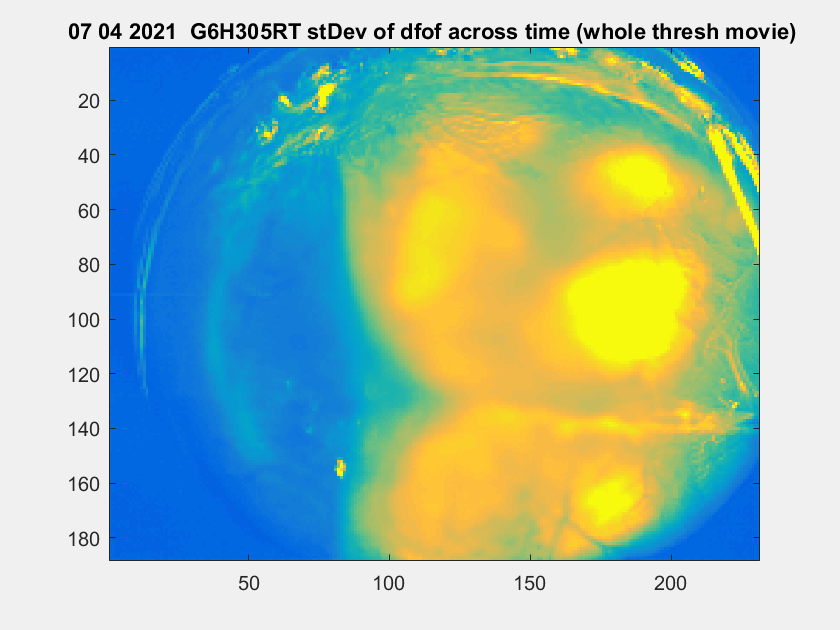

% DO the CROP
% crop manually by picking top left and then bottom right corners of a rectangle
[xPtsCrop yPtsCrop] = ginput(2);

dfCROP = df(yPtsCrop(1):yPtsCrop(2),xPtsCrop(1):xPtsCrop(2),:); % cropping df to be area I select 

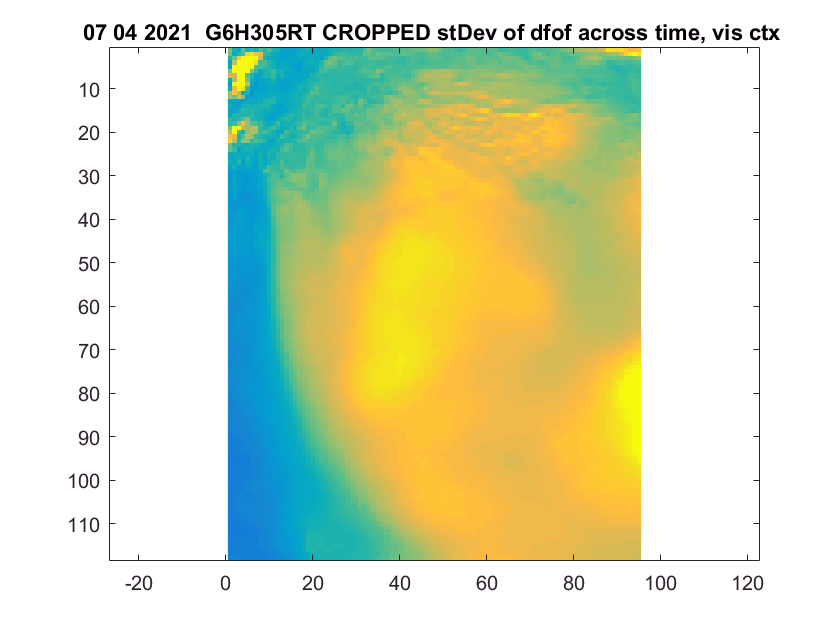

% SHOW the CROPPED image� 
stdMap = std(dfCROP(:,:,1:10:end),[],3); 
figure
% range = 0.045;
imagesc(stdMap,[0 0.04])
% colormap jet
axis equal
clear titleText
titleText = 'CROPPED stDev of dfof across time, vis ctx';
title(sprintf('%s ',date,subjName,titleText))

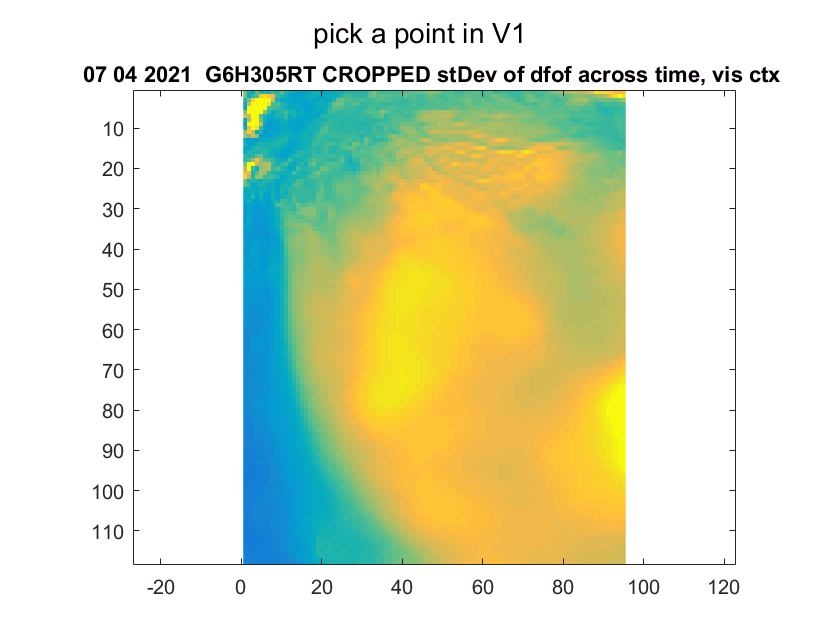

% in this script, no need to get onset chunks, 
% no need to get basline or peak points in order to macke act image - 
% just pick a point in V1
% baslineing can heppen during my con dur for loops/plotting etc,
% cuz it's a trial by trial thing, and right now I just want raw dfof
% for the whole movie

% pick 1 pt - V1

clear xPickedPts 
clear yPickedPts 

% show activation image
% figure_1
suptitle('pick a point in V1')

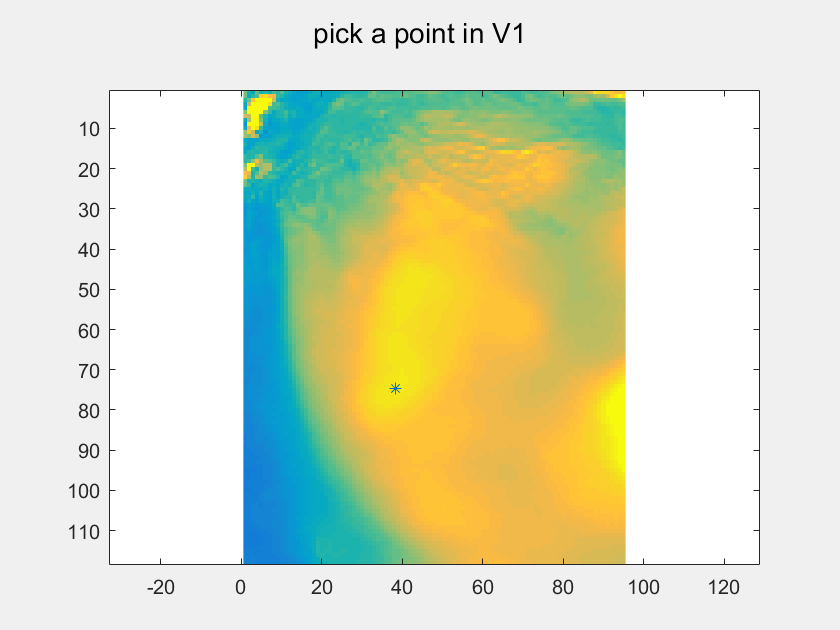


range = [0 0.04]; 
imagesc(stdMap,range)
axis equal
% colormap('jet');
 
for i = 1:1
   
    hold on
    [xPickedPt(i) yPickedPt(i)] = ginput(1);
    plot(xPickedPt(i),yPickedPt(i),'*');
   
end

% SELECT PTS from DF_CROP

roundXpt= round(abs(yPickedPt)); %switch x & y
roundYpt = round(abs(xPickedPt));

dfofV1Point = dfCROP(roundXpt,roundYpt,:); % one point, all frames)
dfofV1Point = squeeze(dfofV1Point);
dfofV1Point = dfofV1Point'

dfofV1Point =     0.0963    0.1051    0.0902    0.0838    0.0773    0.0786    0.0761    0.0745    0.0725    0.0747    0.0789    0.0672    0.0565    0.0546    0.0521    0.0656    0.0775    0.0978    0.0906    0.0841    0.0772    0.0600    0.0454    0.0383    0.0310    0.0318    0.0330    0.0309    0.0309    0.0345    0.0281    0.0246    0.0192    0.0186    0.0120    0.0119    0.0122    0.0134    0.0072    0.0258    0.0437    0.0790    0.1021    0.1021    0.1053    0.1004    0.0885    0.0770    0.0639    0.0592


sizeDfofV1Point = size(dfofV1Point)

sizeDfofV1Point =            1       46044


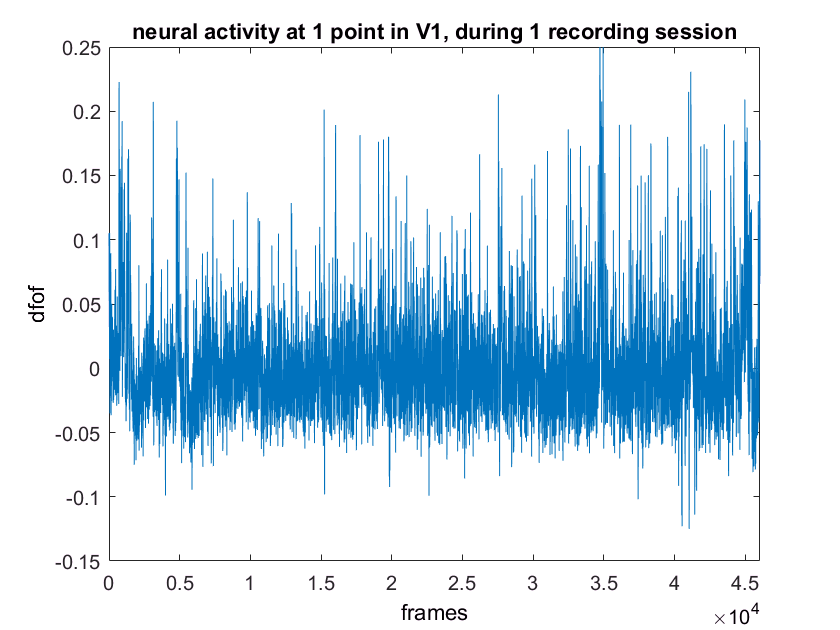


x_axis = [1:length(dfofV1Point)];
figure
plot(x_axis,dfofV1Point)
xlabel('frames')
ylabel('dfof')
title('neural activity at 1 point in V1, during 1 recording session')
xlim([0 length(dfofV1Point)])
ylim([-0.15 0.25])